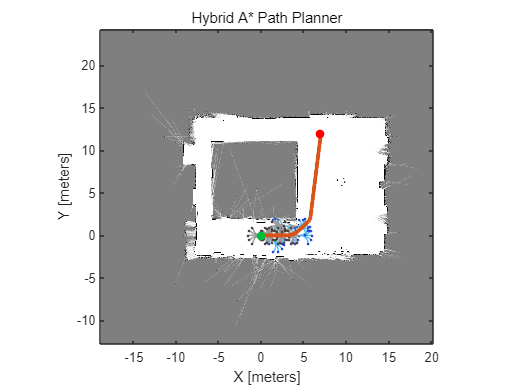

load lhd1sam0.545.mat

% path planning
ss = stateSpaceSE2;
sv = validatorOccupancyMap(ss);
% exmap = occupancyMap(occGrid, 10);
% sv.Map = exmap;
sv.Map = Map;
sv.ValidationDistance = 0.4;
ss.StateBounds = [Map.XWorldLimits; Map.YWorldLimits; [-pi pi]];
planner = plannerHybridAStar(sv,'MinTurningRadius',1,'MotionPrimitiveLength',1.5);
start1 = [0 0 0];
goal = [7 12 pi/2];
refpath = plan(planner,start1,goal);
show(planner)

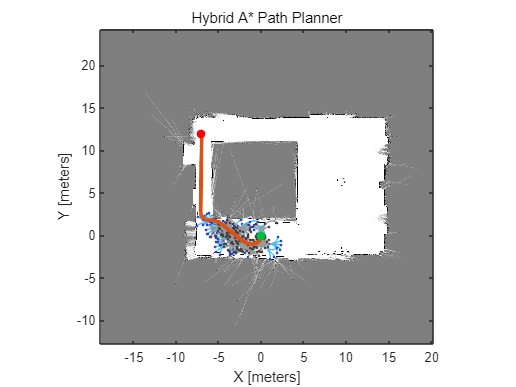

start2 = [0 0 -pi/2];
goal2 = [-7 12 pi/2];
planner2 = plannerHybridAStar(sv,'MinTurningRadius',1,'MotionPrimitiveLength',1.5);
refpath2 = plan(planner2,start2,goal2);
show(planner2)

% Define Waypoints
path = refpath.States(:, 1:2);
robotInitialLocation = path(1,:);
robotGoal = path(end,:);

initialOrientation = 0;

robotCurrentPose = [robotInitialLocation initialOrientation]';

% Create a Kinematic Robot Model
% robot = differentialDriveKinematics("TrackWidth", 0.4, ...
%     "VehicleInputs", "VehicleSpeedHeadingRate", "WheelRadius", 0.085);
robot = differentialDriveKinematics("TrackWidth", 0.4, ...
    "VehicleInputs", "VehicleSpeedHeadingRate", "WheelRadius", 0.085);
%%%%%%%% VehicleInputs 실험 필요

% figure; plot(path(:,1), path(:,2),'k--d')

% Define the Path Following Controller
controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.3;
controller.MaxAngularVelocity = 0.3;
controller.LookaheadDistance = 1;

% Using the Path Following Controller, Drive the Robot over the Desired Waypoints
goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);

% Initialize the simulation loop
sampleTime = 0.545; % 0.545;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = 0.4/0.2;
% frameSize = robot.TrackWidth/0.2;

v_vector = [];
omega_vector = [];
i=1;
v_vel = [];
while( distanceToGoal > goalRadius)
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
%     v_vel = [v_vel; vel'];
    v_vector(i) = v*1000;
    omega_vector(i) = omega*1000;
    i=i+1;

    % Update the plot
    hold off
    
    % Plot path each instance so that it stays persistent while robot mesh
    % moves
    plot(path(:,1), path(:,2),"k--d")
    axis([-10 10 -5 15])
    hold all
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", ...
        "Parent", gca, "View","2D", "FrameSize", frameSize);
    light;
    
    waitfor(vizRate);
end

% 직선은 0.15m/s 각속도는 그대로 받아서 사용
% linear range : [-3000 3000]
% angular range : [-2523 2523]
% typecast(swapbytes(int16(x)), "uint8")

vv = [];
for i=1:length(v_vector)
    vv{i} = typecast(swapbytes(int16(v_vector(i))), "uint8");
end

ome = [];
for i=1:length(omega_vector)
    ome{i} = typecast(swapbytes(int16(omega_vector(i))), "uint8");
end

% ROTATION 0.54s, length 20, int16(295*0.54) rad/s
sampleTime = 0.545;
vizRate = rateControl(1/sampleTime);
TxMsg = canMessage(273, false, 8);

for k=1:length(ome)
    TxMsg.Data = ([vv{k} ome{k} 0 0 0 0]);
%     TxMsg.Data = ([0 0 ome{k} 0 0 0 0]);
    transmit(scout,TxMsg)
    waitfor(vizRate);
end

% real-time 
% Define Waypoints

% path = refpath.States(:, 1:2);
robotInitialLocation = path(1,:);
robotGoal = path(end,:);

initialOrientation = 0;

robotCurrentPose = [robotInitialLocation initialOrientation]';

% Create a Kinematic Robot Model
robot = differentialDriveKinematics("TrackWidth", 0.4, ...
    "VehicleInputs", "VehicleSpeedHeadingRate", "WheelRadius", 0.085);

% Define the Path Following Controller
controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.3;
controller.MaxAngularVelocity = 0.3;
controller.LookaheadDistance = 1;

% Using the Path Following Controller, Drive the Robot over the Desired Waypoints
goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);

% Initialize the simulation loop
sampleTime = 0.545; % 0.1;
vizRate = rateControl(1/sampleTime);


while( distanceToGoal > goalRadius)
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2, :) - robotGoal(:));
    
    vv = typecast(swapbytes(int16(v*1000)), "uint8");
    ome = typecast(swapbytes(int16(omega*1000)), "uint8");

    TxMsgs = canMessage(273, false, 8);
    TxMsgs.Data = ([vv ome 0 0 0 0]);
    transmit(scout,TxMsgs)
    waitfor(vizRate);
end
